# Modelo de CD_CI - Phantom

Juan Nicolás Carvajal Useche

Edgar Giovanny Obregón Espitia

Mediciones

clear all
%Mediciones con el calibrador
B= 90; %base
L1 = 45;
L2 = 105;
L3 = 105;
L4 = 75;
T = 20; %Distancia al centro del gripper

Cinemática directa

Base = MTH(0,B,0,0)

Base =      1     0     0     0
     0     1     0     0
     0     0     1    90
     0     0     0     1


L(1) = Link('revolute', 'd' , L1 , 'a' , 0 , 'alpha' , pi/2 , 'offset' , 0 , 'qlim' , [0 2*pi] ); 
L(2) = Link('revolute', 'd' , 0 , 'a' , L2,'alpha' , 0 , 'offset' , pi/2 , 'qlim' , [0 2*pi] );     
L(3) = Link('revolute', 'd' , 0, 'a' , L3 ,'alpha' , 0 , 'offset' , 0 , 'qlim' , [0 2*pi] );     
L(4) = Link('revolute', 'd' , 0 , 'a' , L4 , 'alpha' , 0 , 'offset' , 0 , 'qlim' , [0 2*pi] );  
TC=rt2tr(rotx(90,"deg")*roty(90,"deg"),[T 0 0]')

TC =      0     0     1    20
     1     0     0     0
     0     1     0     0
     0     0     0     1



Phantom = SerialLink(L,'name','Phantom','tool',TC,'base',Base)

 
Phantom = 
 
Phantom:: 4 axis, RRRR, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         45|          0|     1.5708|          0|
|  2|         q2|          0|        105|          0|     1.5708|
|  3|         q3|          0|        105|          0|          0|
|  4|         q4|          0|         75|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0, 0, 90), RPY/xyz = (0, 0, 0) deg                 
tool:    t = (20, 0, 0), RPY/xyz = (0, 90, 90) deg               
 



syms L1s L2s L3s L4s q1 q2 q3 q4

TB1 = Base

TB1 =      1     0     0     0
     0     1     0     0
     0     0     1    90
     0     0     0     1


T10 = MTH(0,L1s,90,q1)

$$T10 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{1}}{180}\right) & 0 & \sin\left(\frac{\pi \,q_{1}}{180}\right) & 0\\ \sin\left(\frac{\pi \,q_{1}}{180}\right) & 0 & -\cos\left(\frac{\pi \,q_{1}}{180}\right) & 0\\ 0 & 1 & 0 & \mathrm{L1s}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T21 = MTH(L2s,0,0,q2+90)

$$T21 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left(q_{2}+90\right)}{180}\right) & -\sin\left(\frac{\pi \,\left(q_{2}+90\right)}{180}\right) & 0 & \mathrm{L2s}\,\cos\left(\frac{\pi \,\left(q_{2}+90\right)}{180}\right)\\ \sin\left(\frac{\pi \,\left(q_{2}+90\right)}{180}\right) & \cos\left(\frac{\pi \,\left(q_{2}+90\right)}{180}\right) & 0 & \mathrm{L2s}\,\sin\left(\frac{\pi \,\left(q_{2}+90\right)}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T32 = MTH(L3s,0,0,q3)

$$T32 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{3}}{180}\right) & -\sin\left(\frac{\pi \,q_{3}}{180}\right) & 0 & \mathrm{L3s}\,\cos\left(\frac{\pi \,q_{3}}{180}\right)\\ \sin\left(\frac{\pi \,q_{3}}{180}\right) & \cos\left(\frac{\pi \,q_{3}}{180}\right) & 0 & \mathrm{L3s}\,\sin\left(\frac{\pi \,q_{3}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T43 = MTH(L4s,0,0,q4)

$$T43 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{4}}{180}\right) & -\sin\left(\frac{\pi \,q_{4}}{180}\right) & 0 & \mathrm{L4s}\,\cos\left(\frac{\pi \,q_{4}}{180}\right)\\ \sin\left(\frac{\pi \,q_{4}}{180}\right) & \cos\left(\frac{\pi \,q_{4}}{180}\right) & 0 & \mathrm{L4s}\,\sin\left(\frac{\pi \,q_{4}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Cinemática directa 
T40 = TB1*T10*T21*T32*T43*TC

1.  Punto para referenciar Home

home = [0,0,0,-pi/2,0]; %valores de las articulaciones
%csvwrite('trayHome.csv',home)

2. Punto de acercamiento a la herramienta (gripper en frente antes de aproximarse, a una distancia del suelo D)

h_aire = 100; %%%%%%%%%%%%%%%%%%
herr = [0, 180, h_aire, 0]; %Coordenadas XYZ en mm, orientación en rad
[q1f,q2f,q3f,q4f,q5f] = CI(herr(1)-T,herr(2),herr(3)-B,herr(4),L1,L2,L3,L4);
q_n = [q1f;q2f;q3f;q4f;0]';

%csvwrite('trayH1.csv',q_n)

3. Trayectoria de aproximación horizontal al marcador (sin agarrar)

%[Q, QD, QDD, PP] = quinticpolytraj(WAYPOINTS, TIMEPOINTS, T)

p0 = herr;
pf = [0,240,100,0]; %Coordenadas XYZ en mm, orientación en rad
n = 5; %número de puntos
xw = linspace(p0(1),pf(1),n);
yw = linspace(p0(2),pf(2),n);
zw = linspace(p0(3),pf(3),n);

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:n 
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(i)-T,yw(i),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = 0;
end

q_n1 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

4. Punto pa agarrar el marcador

aG = deg2rad(54); %valor de la articulación de cierre del gripper

q_n2 = [q1_n(end);q2_n(end);q3_n(end);q4_n(end);aG]';

5. Punto para subir el gripper con el marcador ya sujetado

n = 10; zw = linspace(zw(end),zw(end)+50,n); %sube 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:n 
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(end)-T,yw(end),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n3 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

6. Trayectoria de alejamiento del portaherramienta (horizontal)

n = 10; yw = linspace(yw(end),yw(end)-50,n); %se aleja 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:n 
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(end)-T,yw(i),zw(end)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n4 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

q_n = [q_n1;q_n2;q_n3;q_n4];

%csvwrite('trayH2.csv',q_n)

7. Punto de acercamiento al círculo externo del espacio de trabajo

rout = 285; %Diámetros de los círculos del workspace
h_aire = 150;
[xwo,ywo,zwo] = workspace(rout,n); %generación de circunferencia
zwo = zwo + h_aire; %ajuste de Z de altura
[q1f,q2f,q3f,q4f,q5f] = CI(xwo(1)-T,ywo(1),zwo(1)-B,pf(4),L1,L2,L3,L4);
q_n = [q1f;q2f;q3f;q4f;aG]';

%csvwrite('trayWO1.csv',q_n)

8. Trayectora para bajar el marcador a la superficie del tablero

[xwo,ywo,zwo] = workspace(rout,n); %generación de circunferencia
h_tablero = 85; zwo = zwo + h_tablero; %ajuste de Z de altura del tablero
n = 10; zw = linspace(zw(end),zwo(end),n); %baja 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xwo(1)-T,ywo(1),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n1 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

9. Dibujar circunferencia externa del workspace

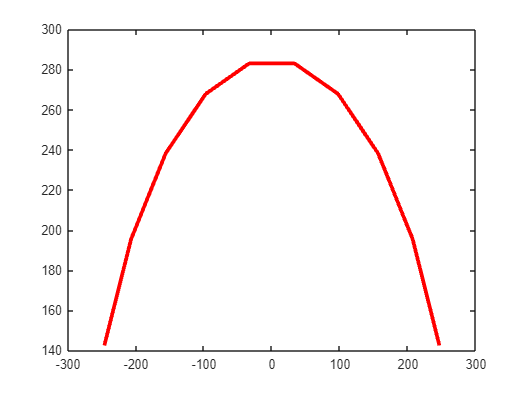

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xwo(i)-T,ywo(i),zw(end)-B,pf(4),L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

%rotación para corregir el plot
for i=1:length(xwo)
     a = rotz(30,'deg')*[xwo(i);ywo(i);0];
     xwp(i) = a(1);
     ywp(i) = a(2);

end

figure(1)
plot(xwp,ywp,'linewidth',3,'Color','r')
hold on



q_n2 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

10. Subir marcador tras dibujar la circunferencia

[xwo,ywo,zwo] = workspace(rout,n); %generación de circunferencia
zwo = zwo + h_aire; %ajuste de Z de altura del tablero
n = 10; zw = linspace(zw(end),zwo(end),n); %sube 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xwo(end)-T,ywo(end),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n3 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

q_n = [q_n1;q_n2;q_n3];

%csvwrite('trayWO2.csv',q_n)

11. Punto de acercamiento al círculo interno del espacio de trabajo

rout = rout - 120; %Diferencia entre diámetro interno y externo
n=15;
[xwo,ywo,zwo] = workspace(rout,n); %generación de circunferencia
zwo = zwo + h_aire; %ajuste de Z de altura
[q1f,q2f,q3f,q4f,q5f] = CI(xwo(1)-T,ywo(1),zwo(1)-B,pf(4),L1,L2,L3,L4);
q_n = [q1f;q2f;q3f;q4f;aG]';

%csvwrite('trayWI1.csv',q_n)

12. Trayectora para bajar el marcador a la superficie del tablero

[xwo,ywo,zwo] = workspace(rout,n); %generación de circunferencia
h_tablero = 60; zwo = zwo + h_tablero; %ajuste de Z de altura del tablero
n = 15; zw = linspace(h_aire,zwo(end),n); %baja 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xwo(1)-T,ywo(1),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

%q_n1 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

13. Dibujar circunferencia interna del workspace

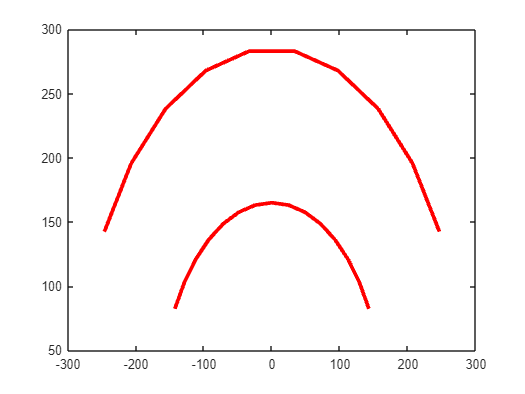

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xwo(i)-T,ywo(i),zw(end)-B,pf(4),L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

%rotación para corregir el plot
for i=1:length(xwo)
     a = rotz(30,'deg')*[xwo(i);ywo(i);0];
     xwp(i) = a(1);
     ywp(i) = a(2);

end

figure(1)
plot(xwp,ywp,'linewidth',3,'Color','r')
hold on



q_n2 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

14. Subir marcador tras dibujar la circunferencia

[xwo,ywo,zwo] = workspace(rout,n); %generación de circunferencia
zwo = zwo + h_aire; %ajuste de Z de altura del tablero
n = 10; zw = linspace(zw(end),zwo(end),n); %sube 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xwo(end)-T,ywo(end),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n3 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

q_n = [q_n1;q_n2;q_n3];

%csvwrite('trayWI2.csv',q_n)

15. Punto de acercamiento a letra N

%Generar puntos
xo = 180; yo = 120; zo=h_aire; %Punto inicial de la letra
[xwo,ywo,zwo] = LetN(n);
xw = xo+xwo;
yw = yo+ywo;
zw = zo+zwo;

[q1f,q2f,q3f,q4f,q5f] = CI(xw(1)-T,yw(1),zw(1)-B,pf(4),L1,L2,L3,L4);
q_n = [q1f;q2f;q3f;q4f;aG]';

%csvwrite('trayN1.csv',q_n)

16. Trayectora para bajar el marcador a la superficie del tablero

zwo = zwo + h_tablero; %ajuste de Z de altura del tablero
n = 10; zw = linspace(zw(end),zwo(end),n); %baja 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(1)-T,yw(1),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n1 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

17. Dibujar letra

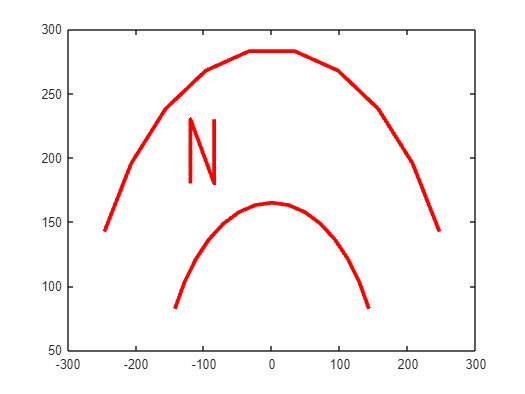

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(xw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(i)-T,yw(i),zw(end)-B,pf(4),L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

%rotación para corregir el plot
for i=1:length(xw)
     a = rotz(90,'deg')*[xw(i);yw(i);0];
     xwp(i) = a(1);
     ywp(i) = a(2);

end

figure(1)
plot(xwp,ywp,'linewidth',3,'Color','r')
hold on


q_n2 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

18. Subir marcador tras dibujar la letra

zwo = zwo + h_aire; %ajuste de Z de altura del tablero
n = 10; zw = linspace(zw(end),zwo(end),n); %sube 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(end)-T,yw(end),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n3 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

q_n = [q_n1;q_n2;q_n3];

%csvwrite('trayN2.csv',q_n)

19. Punto para acercarse a la G

%Generar puntos
xo = 190; yo = 0; zo=h_aire; %Punto inicial de la letra
[xwo,ywo,zwo] = LetG(n);
xw = xo+xwo;
yw = yo+ywo;
zw = zo+zwo;

[q1f,q2f,q3f,q4f,q5f] = CI(xw(1)-T,yw(1),zw(1)-B,pf(4),L1,L2,L3,L4);
q_n = [q1f;q2f;q3f;q4f;aG]';

%csvwrite('trayG1.csv',q_n)

20. Trayectora para bajar el marcador a la superficie del tablero

zwo = zwo + h_tablero+5; %ajuste de Z de altura del tablero
n = 10; zw = linspace(zw(end),zwo(end),n); %baja 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(1)-T,yw(1),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n1 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

21. Dibujar letra

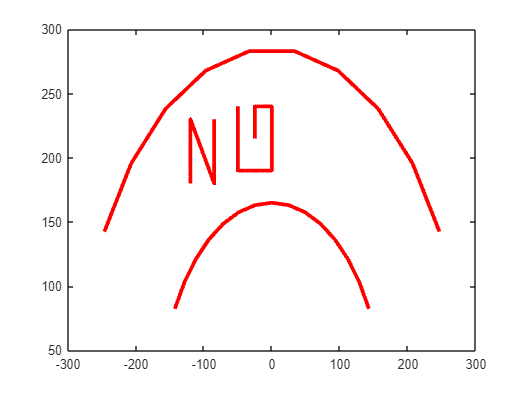

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n); q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(xw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(i)-T,yw(i),zw(end)-B,pf(4),L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

%rotación para corregir el plot
for i=1:length(xw)
     a = rotz(90,'deg')*[xw(i);yw(i);0];
     xwp(i) = a(1);
     ywp(i) = a(2);

end

figure(1)
plot(xwp,ywp,'linewidth',3,'Color','r')
hold on


q_n2 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

22. Subir marcador tras dibujar la letra

zwo = zwo + h_aire; %ajuste de Z de altura del tablero
n = 10; zw = linspace(zw(end),zwo(end),n); %sube 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(end)-T,yw(end),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n3 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

q_n = [q_n1;q_n2;q_n3];

%csvwrite('trayG2.csv',q_n)

23. Acercamiento a la figurita

%Generar puntos
h_air = 150; h_tablero = 60;
xo = 190; yo = -115; zo=h_aire; %Punto inicial de la letra
[xwo,ywo,zwo,x,y] = figurita(10,h_tablero,h_aire);
xw = xo+xwo; x = xo+x;
yw = yo+ywo; y = yo+y;
zw = zo+zwo;

[q1f,q2f,q3f,q4f,q5f] = CI(xw(1)-T,yw(1),zw(1)-B,pf(4),L1,L2,L3,L4);
q_n = [q1f;q2f;q3f;q4f;aG]';

%csvwrite('trayF1.csv',q_n)

24. Trayectora para bajar el marcador a la superficie del tablero

zwo = zwo + h_tablero; %ajuste de Z de altura del tablero
n = 10; zw = linspace(h_air,h_tablero,n); %baja 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(1)-T,yw(1),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n1 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

25. Dibujar figurita

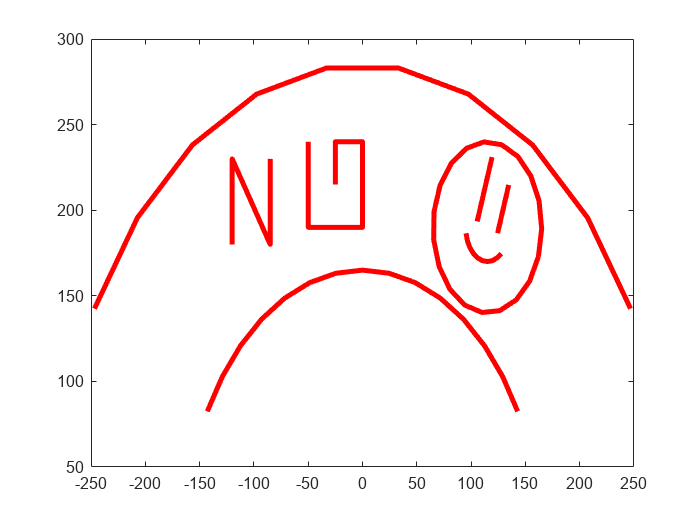

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);
[xwo,ywo,zw] = figurita(10,h_tablero,h_aire);
for i=1:length(xw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(i)-T,yw(i),zw(i)-B,pf(4),L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end


%rotación para corregir el plot
for i=1:length(x)
     a = rotz(90,'deg')*[x(i);y(i);0];
     xwp(i) = a(1);
     ywp(i) = a(2);

end

figure(1)
plot(xwp(1:20),ywp(1:20),'g','linewidth',3,'Color','r')
hold on
plot(xwp(21:30),ywp(21:30),'g','linewidth',3,'Color','r')
hold on
plot(xwp(31:40),ywp(31:40),'g','linewidth',3,'Color','r')
hold on
plot(xwp(41:50),ywp(41:50),'g','linewidth',3,'Color','r<')
hold off

saveas(figure(1),'r12.png');


q_n2 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

26. Subir marcador tras dibujar la figurita

zwo = zwo + h_air; %ajuste de Z de altura del tablero
n = 3; zw = linspace(zw(end),zwo(end),n); %sube 5cm

%Generar CI
q1_n = zeros(0,n);q2_n = zeros(0,n);q3_n = zeros(0,n);q4_n = zeros(0,n); q5_n = zeros(0,n);

for i=1:length(zw)
    [q1f,q2f,q3f,q4f,q5f] = CI(xw(end)-T,yw(end),zw(i)-B,0,L1,L2,L3,L4);
    q1_n(i) = q1f;
    q2_n(i) = q2f;
    q3_n(i) = q3f;
    q4_n(i) = q4f;
    q5_n(i) = aG;
end

q_n3 = [q1_n;q2_n;q3_n;q4_n;q5_n]';

q_n = [q_n1;q_n2;q_n3];

%csvwrite('trayF2.csv',q_n)

Fotos para la interfaz

% [xwo,ywo,zwo] = figurita(10,h_tablero,h_aire);
% plot(xwo,ywo,linewidth,3)
% axis([-100 100 -100 100])
% hold off
% [xwo,ywo,zwo] = LetN(10);
% plot(xwo,ywo,linewidth,3)
% axis([-100 100 -100 100])
% hold on
% [xwo,ywo,zwo] = LetG(10);
% plot(-70+xwo,ywo,linewidth,3)
% axis([-100 100 -100 100])
% hold off
% [xwo,ywo,zwo] = workspace(285,10);
% plot(xwo,ywo,linewidth,3)
% hold on
% [xwo,ywo,zwo] = workspace(285-120,10);
% plot(xwo,ywo)

Funciones usadas

function [Res] = MTH(a,d,alpha,theta)
Res = [cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta); 
       sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta); 
       0 sind(alpha) cosd(alpha) d; 
       0 0 0 1];
end

function [theta_1,theta_2,theta_3,theta_4,theta_5] = CI(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)

% Cálculos
theta_1 = atan2(P_y, P_x);

r = sqrt(P_x^2 + P_y^2);
D_z = P_z - L_4*sin(beta) - L_1;
D_r = r - L_4*cos(beta);

theta_2 = -2*atan((2*D_r*L_2 - sqrt(-D_r^4 - 2*D_r^2*D_z^2 + 2*D_r^2*L_2^2 + 2*D_r^2*L_3^2 - D_z^4 + 2*D_z^2*L_2^2 + 2*D_z^2*L_3^2 - L_2^4 + 2*L_2^2*L_3^2 - L_3^4))/(D_r^2 + D_z^2 + 2*D_z*L_2 + L_2^2 - L_3^2));

theta_3 = -2*atan((sqrt((-D_r^2 - D_z^2 + L_2^2 + 2*L_2*L_3 + L_3^2)*(D_r^2 + D_z^2 - L_2^2 + 2*L_2*L_3 - L_3^2)) - 2*L_2*L_3)/(D_r^2 + D_z^2 - L_2^2 - L_3^2));

theta_4 = beta - theta_2 - theta_3 ;

theta_5 = deg2rad(90);

theta_3 = theta_3 - pi/2;

end

function [x_coords, y_coords, z_coords] = workspace(r,n)
    theta = linspace(0,120,n);
    x_coords = r*cosd(theta);
    y_coords = r*sind(theta);
    z_coords = 0*ones(1,n);
end

function [x_coords, y_coords, z_coords] = LetN(n)

    % Definir los puntos para cada trazo
    trazo1 = [zeros(1,n);linspace(0,50,n);zeros(1,n)]';
    trazo2 = [linspace(0,35,n);linspace(50,0,n);zeros(1,n)]';
    trazo3 = [35*ones(1,n);linspace(0,50,n);zeros(1,n)]';
    % Concatenar los trazos para formar la letra "N"
    letra_N = [trazo1; trazo2;trazo3];
    % Extraer las coordenadas x e y
    x_coords = letra_N(:, 1);
    y_coords = letra_N(:, 2);
    z_coords = letra_N(:,3);
    for i=1:length(x_coords)
         a = rotz(-90,'deg')*[x_coords(i);y_coords(i);z_coords(i)];
         x_coords(i) = a(1);
         y_coords(i) = a(2);
         z_coords(i) = a(3);
    end    

end

function [x_coords, y_coords,z_coords] = LetG(n)


    % Definir los puntos para cada trazo
    trazo1 = [linspace(50,0,n);50*ones(1,n);zeros(1,n)]';
    trazo2 = [zeros(1,n);linspace(50,0,n);zeros(1,n)]';
    trazo3 = [linspace(0,50,n);zeros(1,n);zeros(1,n)]';
    trazo4 = [50*ones(1,n);linspace(0,25,n);zeros(1,n)]';
    trazo5 = [linspace(50,25,n);25*ones(1,n);zeros(1,n)]';
    % Concatenar los trazos para formar la letra "N"
    letra_G = [trazo1; trazo2;trazo3; trazo4;trazo5];
    % Extraer las coordenadas x e y
    x_coords = letra_G(:, 1);
    y_coords = letra_G(:, 2);
    z_coords = letra_G(:,3);

end

function [x_coords, y_coords,z_coords,x,y] = figurita(n,h_tablero,h_aire)
    
    r = 50;
    t = linspace(0,2*pi,2*n);
    %círculo
    tx1 = r*cos(t);
    ty1 = r*sin(t);
    tz1 = h_tablero*ones(1,2*n);
    %subir marcador
    tx2 = tx1(end)*ones(1,2);
    ty2 = ty1(end)*ones(1,2);
    tz2 = linspace(h_tablero,h_aire,2);
    %llevar marcador al primer ojo
    tx3 = -10;
    ty3 = 40;
    tz3 = tz2(end);
    %bajar marcador
    tz4 = linspace(h_aire,h_tablero,2);  
    tx4 = -10*ones(1,length(tz4));
    ty4 = 40*ones(1,length(tz4));
    %ojo
    trazo5 = [-10*ones(1,n);linspace(40,0,n);zeros(1,n)+h_tablero];
    %subir marcador
    tx6 = -10*ones(1,2);
    ty6 = 0*ones(1,2);
    tz6 = linspace(h_tablero,h_aire,2);
    %llevar marcador al segundo ojo
    tx7 = 10; 
    ty7 = 40;
    tz7 = tz6(end);
    %bajar marcador
    tz8 = linspace(h_aire,h_tablero,2);  
    tx8 = 10*ones(1,length(tz8));
    ty8 = 30*ones(1,length(tz8));
    %ojo2
    trazo9 = [10*ones(1,n);linspace(30,0,n);zeros(1,n)+h_tablero];
    %subir marcador
    tx10 = 10*ones(1,2);
    ty10 = 0*ones(1,2);
    tz10 = linspace(h_tablero,h_aire,2);
    %llevar marcador a la boca
    r = 20;
    tx11 = r*cos(pi+(pi/6));
    ty11 = r*sin(pi+(pi/6));
    tz11 = tz10(end);
    
    %bajar marcador
    tz12 = linspace(h_aire,h_tablero,2); 
    tx12 = tx11*ones(1,length(tz12));
    ty12 = ty11*ones(1,length(tz12));

    %boca
    t = linspace(pi+(pi/6),2*pi-(pi/6),n);
    tx13 = r*cos(t);
    ty13 = r*sin(t);
    tz13 = zeros(1,n)+h_tablero;

    %concatenar'
    x_coords = [tx1,tx2,tx3,tx4,trazo5(1,:),tx6,tx7,tx8,trazo9(1,:),tx10,tx11,tx12,tx13];
    y_coords = [ty1,ty2,ty3,ty4,trazo5(2,:),ty6,ty7,ty8,trazo9(2,:),ty10,ty11,ty12,ty13];
    z_coords = [tz1,tz2,tz3,tz4,trazo5(3,:),tz6,tz7,tz8,trazo9(3,:),tz10,tz11,tz12,tz13];
    x = [tx1,trazo5(1,:),trazo9(1,:),tx13];
    y = [ty1,trazo5(2,:),trazo9(2,:),ty13];

    for i=1:length(x_coords)
        a = rotz(-110,'deg')*[x_coords(i);y_coords(i);z_coords(i)];
        x_coords(i) = a(1);
        y_coords(i) = a(2);
        z_coords(i) = a(3);
    end
    for i=1:length(x)
        a = rotz(-110,'deg')*[x(i);y(i);0];
        x(i) = a(1);
        y(i) = a(2);
        z(i) = a(3);
    end
end
